# **Sesion 2.2.- Creación de un robot con RigidBodyTree **

El objetivo de esta sesión es crear un robot utilizando el [rigidBodyTree](https://es.mathworks.com/help/robotics/ref/rigidbodytree.html) de Matlab. Primero, importar modelos predefinidos en Matlab. Posteriormente, se creará un robot planar de 2 gdl, utilizando transformaciones mediante vectores y utilizando los parámetros DH. Se creara un modelo de un robot planar de 3gdl (modelado de un dedo) utilizando Simscape.

## 1.Utilización de modelos de robot predefinidos en Matlab

Matlab tiene una amplia librería de robots comerciales disponibles para ser importados directamente. Se importan utilizando la función [loadrobot](https://es.mathworks.com/help/robotics/ref/loadrobot.html?searchHighlight=loadrobot&s_tid=srchtitle_loadrobot_1).

clear 
close all
IRB120=loadrobot("abbIrb120",'Gravity',[0 0 -9.81] );
showdetails (IRB120)

--------------------
Robot: (8 bodies)

 Idx     Body Name            Joint Name            Joint Type     Parent Name(Idx)   Children Name(s)
 ---     ---------            ----------            ----------     ----------------   ----------------
   1          base        base_link-base                 fixed         base_link(0)   
   2        link_1               joint_1              revolute         base_link(0)   link_2(3)  
   3        link_2               joint_2              revolute            link_1(2)   link_3(4)  
   4        link_3               joint_3              revolute            link_2(3)   link_4(5)  
   5        link_4               joint_4              revolute            link_3(4)   link_5(6)  
   6        link_5               joint_5              revolute            link_4(5)   link_6(7)  
   7        link_6               joint_6              revolute            link_5(6)   tool0(8)  
   8         tool0          joint6-tool0                 fixed            link_6

show(IRB120);

## 2.Creación del robot planar de 2 gdl mediante la especificación de la posición relativa entre eslabones

El robot planar de 2 gdl que se va a crear es el siguiente:

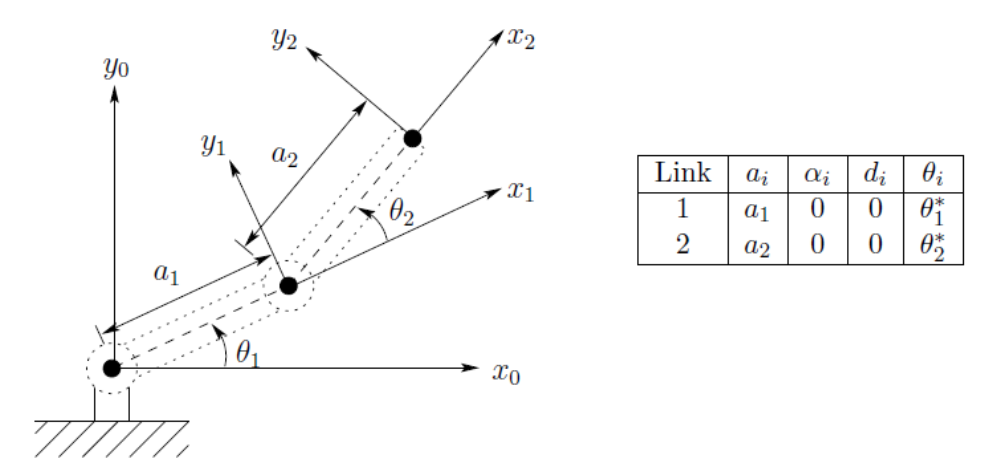

Definimos los párametros geométricos del robot planar de 2 gdl. Además, la articulación 2 tendrá un rango de movimiento límitado de 0 a 180º

clear
close all;

theta1 =0; theta2 = 0;
alpha1 = 0; alpha2 = 0;
a1=0.2; a2=0.1;
joint2Limits = [0, pi];

Creamos el objeto *rigidBodyTree* para construir el robot.Este árbol se inicializa con un marco de coordenadas base al que asociar sólidos.

robot2gdl = rigidBodyTree ('DataFormat', 'column');

Nota: Se definimos que el '`DataForma`t' sea '`colum`' porque por defecto rigidBodyTree trabaja con datos de tipo 'struct' y es mucho más facil trabajar con datos en forma de columnas. También se puede trabajar con datos de tipo 'row' (filas) pero en esta asignatura siempre utilizare columnas.

Crea el primer `rigidBody` y añadelo al robot. Para añadir un `rigidBody`:

- Crea un objeto de tipo `rigidBody` y dale un nombre único.

- Crea un objeto `rigidBodyJoint`  y dale un nombre único. La articulación puede ser del tipo 'fixed', 'revolute' o 'prismatic'. 

- Usa `setFixedTransform` para especificar la transformación entre un cuerpo y otro.

- Llama a la función `addBody` para unir el cuerpo rígido a la base del robot.

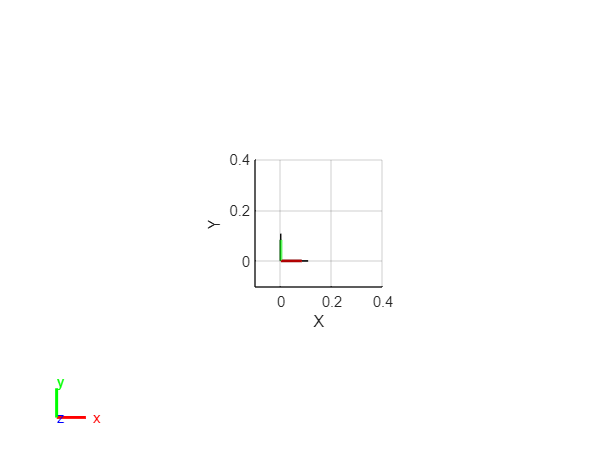

body1 = rigidBody('body1'); %Crear un objeto de sólido rígido 
jnt1 = rigidBodyJoint('jnt1','revolute');  %Crear la articulación. 
jnt1.JointAxis = [0, 0, 1];   %Eje de movimiento de la articulación. 
jnt1.HomePosition = theta1;   %Posicíon por defecto 
%Defina la posición relativa del nuevo eslabón 
tform = trvec2tform([0, 0, 0]);          
setFixedTransform(jnt1,tform); 

%Defina el angulo inicial (q0) de la articulación
body1.Joint = jnt1; 
%Agregue el primer cuerpo al árbol. Especifique que lo está adjuntando a la base del árbol. La transformación fija definida anteriormente es de la base (principal) al primer cuerpo.
addBody(robot2gdl,body1,'base');
show (robot2gdl); view (2); ax = gca; ax.Projection = 'orthographic';  axis ([-0.1 0.4 -0.1 0.4]);

Creamos el segundo sólido rígido. Defina las propiedades de este sólido y adjúntelo al primer sólido rígido. Defina la transformación en relación con el marco del cuerpo anterior.

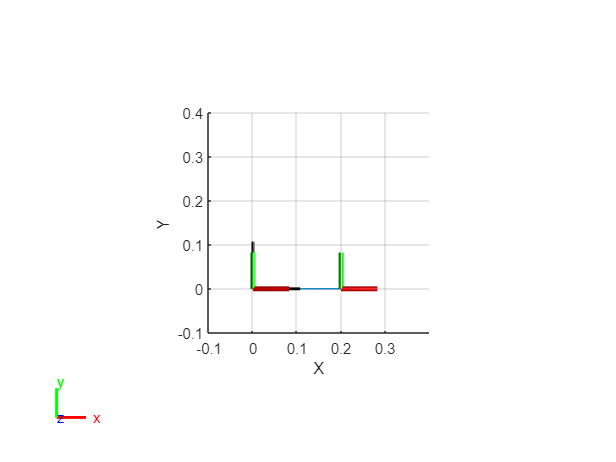

body2 = rigidBody('body2'); 
jnt2 = rigidBodyJoint('jnt2','revolute');
jnt2.JointAxis = [0, 0, 1];   %Eje de movimiento de la articulación. 
jnt2.HomePosition = theta2;  %Defina la posicíon por defecto 
jnt2.PositionLimits = joint2Limits;        %[min max] angle of rotations of the axis (radians)
tform2 = trvec2tform([a1, 0, 0]);  %converts the Cartesian representation of a translation vector, trvec, to the corresponding homogeneous transformation, tform. 
setFixedTransform(jnt2,tform2);
body2.Joint = jnt2; 
addBody(robot2gdl,body2,'body1'); % Add body2 to body1
show (robot2gdl); view (2); ax = gca; ax.Projection = 'orthographic';  axis ([-0.1 0.4 -0.1 0.4]);

Creamos el tercer sólido rígido. 

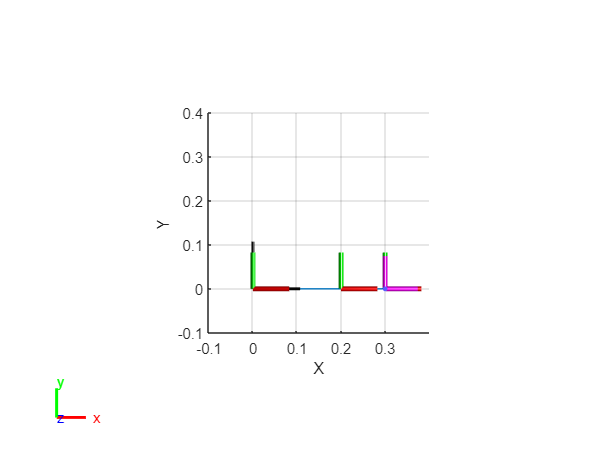

body3 = rigidBody('tool'); 
jnt3 = rigidBodyJoint('jnt3','fixed'); 
tform3 = trvec2tform([a2, 0, 0]);
setFixedTransform(jnt3,tform3); 
body3.Joint = jnt3;
addBody(robot2gdl,body3,'body2');  % Add body3 to body2 
show (robot2gdl); view (2); ax = gca; ax.Projection = 'orthographic';  axis ([-0.1 0.4 -0.1 0.4]);

Verificación que el robot se ha construido correctamente utlizando las funciones `showdetails` o `show`. 

showdetails(robot2gdl)

--------------------
Robot: (3 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   tool(3)  
   3         tool         jnt3        fixed            body2(2)   
--------------------


Podemos guardar el objeto ridigBodyTree en un fichero mat para trabajar posteriormente con él

save robot2gdl.mat robot2gdl

## 3. Creación del robot planar de 2 gdl mediante mediante los parámetros de Denavit-Hartenberg

Vamos a crear el mismo robot planar con 2 gdl pero mediante los parámetros DH

clear;
close all;

Definimos los párametros geométricos del robot planar de 2 gdl (los mismos que antes)

theta1 =0; theta2 = 0;
a1=0.2; a2=0.1;

%           a alpha d   theta
dhparams = [a1  0   0  theta1;
            a2 	0   0  theta2];

joint2Limits = [0, pi];

Se crea el objeto *rigidBodyTree*

robot2gdl_DH = rigidBodyTree ('DataFormat', 'column');

Se crea el primer rigidBody y se añade al robot. Para añadir un rigidBody:

- Crear el objeto `rigidBody` y darle un nombre único.

- Crear el objeto `rigidBodyJoint` o y darle un nombre único.

- Utilizar la función `setFixedTransform` para especificar que la transformación cuerpo a cuerpo se realiza utilizando parámetros DH. **El parámetro thetha se ignora porque este ángulo depende de la posición angular del robot. Por esta razón, es necesario definir los thetas como la posición home de las articulaciones (joint) asociadas a cada eslabón (rigidBody)**

- Utilizar la función `addBody` para añadir el primer cuerpo sólido a la base del robot.

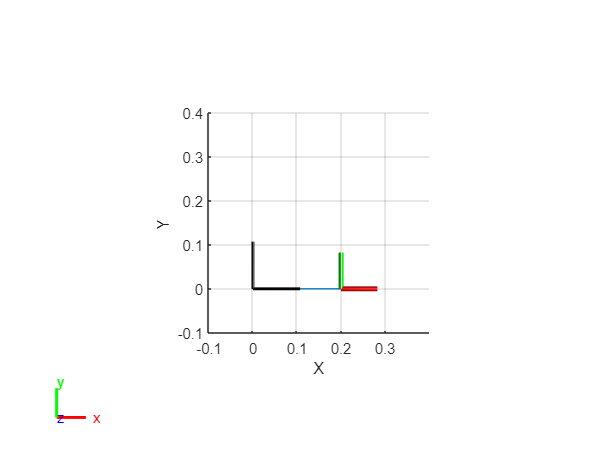

body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');

setFixedTransform(jnt1,dhparams(1,:),'dh');
jnt1.HomePosition = theta1;
body1.Joint = jnt1;

addBody(robot2gdl_DH,body1,'base')
show (robot2gdl_DH); view (2); ax = gca; ax.Projection = 'orthographic';  axis ([-0.1 0.4 -0.1 0.4]);

Crear y añadir el segundo cuerpo rígido al robot. Se debe especificar el nombre del cuerpo rígido previo cuadno se llama a la función `addBody` para añadirlo. 

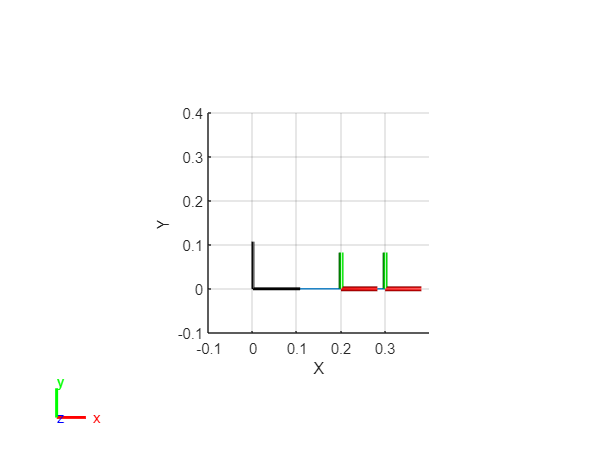

body2 = rigidBody('tool');
jnt2 = rigidBodyJoint('jnt2','revolute');
setFixedTransform(jnt2,dhparams(2,:),'dh');
jnt2.HomePosition = theta2;
jnt2.PositionLimits = joint2Limits;        
body2.Joint = jnt2;
addBody(robot2gdl_DH,body2,'body1')
show (robot2gdl_DH); view (2); ax = gca; ax.Projection = 'orthographic';  axis ([-0.1 0.4 -0.1 0.4]);

Verificar que el robot se ha construido correctamente utilizando las funciones `showdetails` (muestra una lista de todos los cuerpos solidos que componenen el robot) o `show (muestra el robot con la configuraciónpor defecto).`

showdetails(robot2gdl_DH)

--------------------
Robot: (2 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   tool(2)  
   2         tool         jnt2     revolute            body1(1)   
--------------------


Podemos guardar el objeto ridigBodyTree en un fichero mat para trabajar posteriormente con él

save robot2gdl_DH.mat robot2gdl_DH

## 4. Creación de un robot importando el modelo de Simscape

Otra forma de crear un robot (un objeto de tipo RigidBodyTree) es importando un modelo 'Multibody' de 'Simscape'.  Aunque no lo vamos a utilizar en la asignatura, veamos como funciona. 

Abrimos un modelo de Simscape, en concreto un modelo de un dedo:

open_system('dedo.slx')
[modelo_dedo,importInfo] = importrobot(gcs);
modelo_dedo.DataFormat = 'column';
showdetails(modelo_dedo)

--------------------
Robot: (3 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        Body1        Joint1      revolute             Base(0)   Body2(2)  
   2        Body2        Joint2      revolute            Body1(1)   Body3(3)  
   3        Body3        Joint3      revolute            Body2(2)   
--------------------


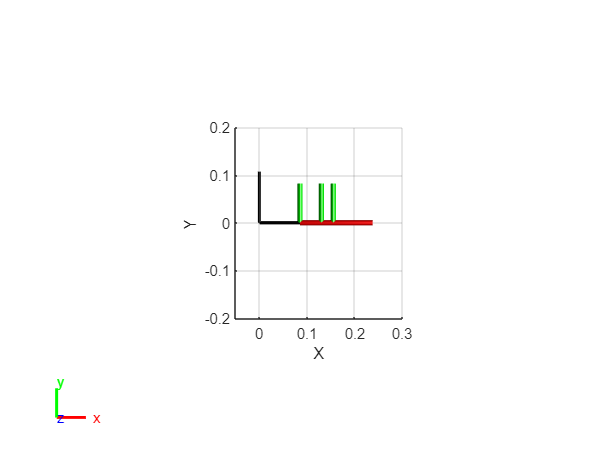

show(modelo_dedo);
view(2);
ax = gca; 
ax.Projection = 'orthographic';  
axis ([-0.05 0.3 -0.2 0.2 ]);

Movamosle:

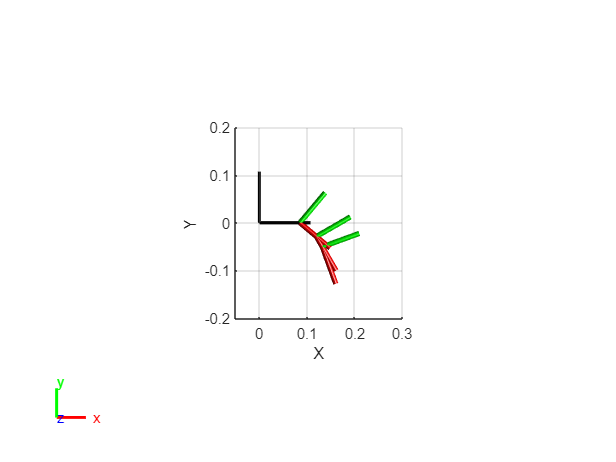

show(modelo_dedo, deg2rad([-40 -20 -10])');
view(2)
ax = gca; 
ax.Projection = 'orthographic';  
axis ([-0.05 0.3 -0.2 0.2 ]);